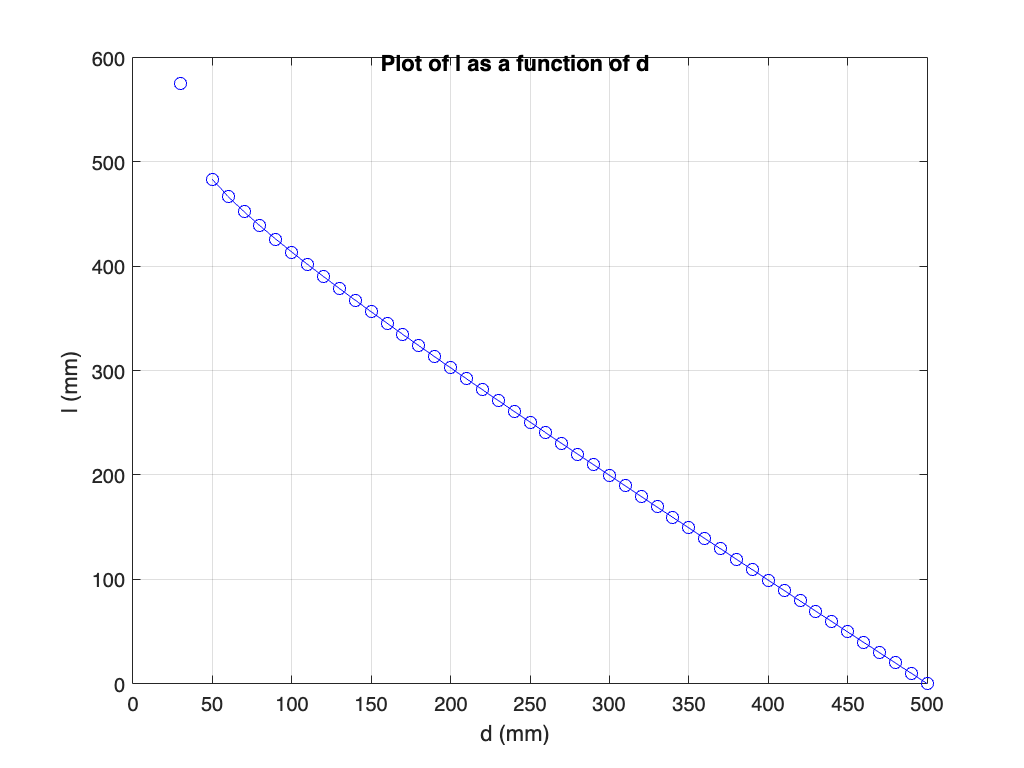

clc; clear; close all;

% Given parameters
a = 200; % mm
d_vals = 30:10:500; % mm
d_min = 30; % mm
d_max = 500; % mm

% Calculation of x
x_max = d_max + a;
x = 500;

% Calculation of alpha
alpha_max1 = asin((x/2) / ((a/2) + d_max));
alpha_max2 = asin((a/2) / ((a/2) + d_min));
alpha = 15 * pi / 180;  % Use pi instead of 3.14 for better precision


% Compute y2 directly without iteration
beta = acos((x/2) / (a/2 + d_max/2));
y2 = ((x/2) * tan(beta)) + d_max/2;

% Precompute sin and cos of alpha for efficiency
sin_alpha = sin(alpha);
cos_alpha = cos(alpha);

% Boundary conditions
l_start = 575;  % l = 575 when d = 30
l_end = 0;      % l = 0 when d = 500

% Initialize l_vals and manually set the first and last values
l_vals = zeros(size(d_vals));
l_vals(1) = l_start;  % Given correct value for the first iteration
l_vals(end) = l_end;  % Enforce boundary condition

l_prev = l_vals(1); % Initialize previous l value

% Iterate from second element to second-to-last element
for i = 2:(length(d_vals)-1)  
    d = d_vals(i);
    syms l
    eq_l = l == (1/cos_alpha) * (y2 - d/2 - sin(acos((x - 2*l*sin_alpha) / (a + d))) * (a/2 + d/2));
    
    sol_l = double(vpasolve(eq_l, l));

    if isempty(sol_l)
        l_vals(i) = NaN; % Assign NaN if no solution is found
    else
        sol_l = real(sol_l); % Ensure real part is taken
        if numel(sol_l) > 1
            % Choose the closest solution to the previous l value
            [~, idx] = min(abs(sol_l - l_prev));
            l_vals(i) = sol_l(idx);
        else
            l_vals(i) = sol_l; % Assign the single real solution
        end
    end
    
    % Apply interpolation correction to enforce boundary values
    l_vals(i) = l_vals(1) + (l_vals(end) - l_vals(1)) * (d_vals(i) - d_vals(1)) / (d_vals(end) - d_vals(1));
    
    % Update the previous l value
    l_prev = l_vals(i);
end

% Plot l as a function of d
figure;
plot(d_vals, l_vals, 'b-o');
xlabel('d (mm)');
ylabel('l (mm)');
title('Plot of l as a function of d');
grid on;


% Display results for d = 500
disp('Results for d = 500 mm:');

Results for d = 500 mm:


disp(['y2: ', num2str(y2)]);

y2: 494.949


disp(['alpha: ', num2str(alpha)]);

alpha: 0.2618


disp(['x: ', num2str(x)]);

x: 500
